% LU decomposition using standard approach
A = delsq(numgrid('L',20));
A = full(A);

% LU decomposition using myLU function
[L_myLU, U_myLU, P_myLU] = myLU(A);

% LU decomposition using lu() function
[L_lu, U_lu, P_lu] = lu(A);

% Compare accuracy of solutions
disp("Accuracy comparison of solutions:")

Accuracy comparison of solutions:


disp("Norm of difference between myLU and lu() solutions for L:")

Norm of difference between myLU and lu() solutions for L:


disp(norm(L_myLU - L_lu));

   4.2915e-16



disp("Norm of difference between myLU and lu() solutions for U:")

Norm of difference between myLU and lu() solutions for U:


disp(norm(U_myLU - U_lu));

   2.1042e-15



disp("Norm of difference between myLU and lu() solutions for P:")

Norm of difference between myLU and lu() solutions for P:


disp(norm(P_myLU - P_lu));

     0



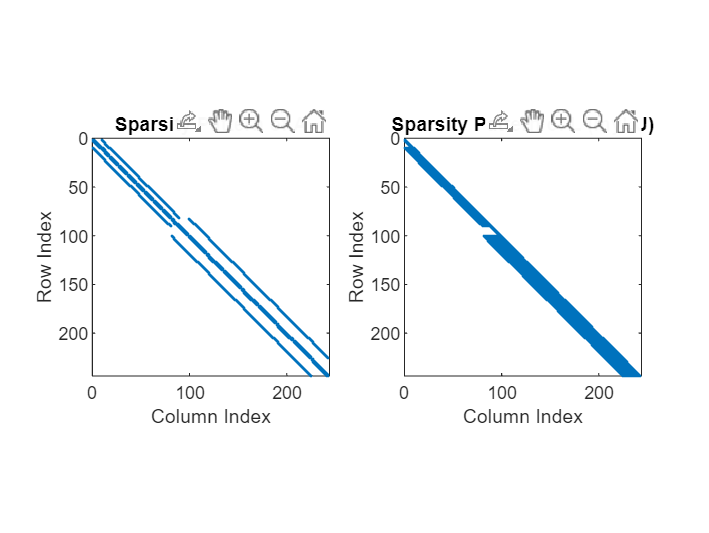


% Plot sparsity pattern of A
figure
subplot(1, 2, 1)
spy(A)
title('Sparsity Pattern of A')
xlabel('Column Index')
ylabel('Row Index')

% Convert LU factors to sparse matrices for visualization
L_sparse = sparse(L_myLU);
U_sparse = sparse(U_myLU);

% Plot sparsity pattern of L from myLU
subplot(1, 2, 2)
spy(L_sparse)
title('Sparsity Pattern of L (myLU)')
xlabel('Column Index')
ylabel('Row Index')

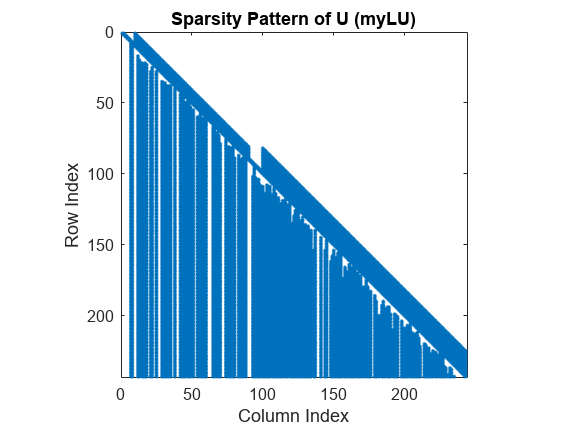


% Plot sparsity pattern of U from myLU
figure
spy(U_sparse)
title('Sparsity Pattern of U (myLU)')
xlabel('Column Index')
ylabel('Row Index')

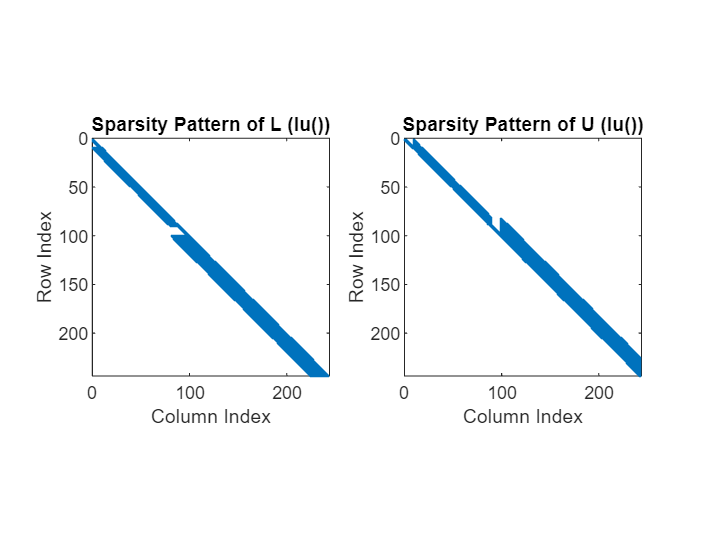


% Plot sparsity pattern of L and U from built-in lu()
figure
subplot(1, 2, 1)
spy(L_lu)
title('Sparsity Pattern of L (lu())')
xlabel('Column Index')
ylabel('Row Index')

subplot(1, 2, 2)
spy(U_lu)
title('Sparsity Pattern of U (lu())')
xlabel('Column Index')
ylabel('Row Index')